# Exercice 11 - Optimisation multi-objectifs 

## Données

Un dispatcher d'énergies dispose de 5  centrales thermiques de différentes technologiques qui produisent de l'électricité. Il est capable de prédire le coût de chaque centrale à partir d'une relation de type : 


$$C_I \left(P_I \right)=a_I {\left(P_I \right)}^2 +b_I {\left(P_I \right)} +c_I$$


$C_I$ est le coût de production selon la puissance produite ($P_I$) pour l'unité *I*. 

Chaque centrale a des limites de production : $P_{I,\min } {\le P}_I \le P_{I,\max }$

Chaque centrale produit des émissions polluantes. Le dispatcher dispose de relation pour estimer la quantité totale ($T_I$) de polluants produite en kg/j par chaque centrale en fonction de sa puissance thermique ($P_I$) :  


$$T_I \left(P_I \right)=d_I {\left(P_I \right)}^2 +e_I {\left(P_I \right)} +f_I$$


Les données des 5 centrales sont disponibles dans le fichier `data_Exercice11.mat` (`load data_Exercice11`): coefficients `A, B, C, D, E` et `F` des deux formules ci-dessus ainsi que `Pmin` et `Pmax`. 

Toutes les puissances sont exprimées en MW.

clear 

load data_Exercice11

## Partie 1

## 1.1) Fonction objectif :

f = @(x) x.^2*A+x*B+sum(C);

## 1.2) Définition des contraintes

Aineq = [];%les contraintes inégalités seront contenues dans les bornes
Bineq=[];
Aeq = [ones(1,length(Pmin))];
%Beq est dans la boucle for pour tracer les 10 histogrammes

## 1.3) Définition des bornes

LB = [Pmin];%borne inférieure
UB =[Pmax];%borne supérieure

## 1.4) Solver : fmincon + Affichage des résultats

x0 = UB'/2; %initialisation
option=optimoptions('fmincon','display','iter');
X=[];
Demandes = [];
Cout_Global = [];
for k = 1:10
    Beq = [335 + 65*k];%toutes les valeurs de Pmin à Pmax
    [x,fval,flag,output]=fmincon(f,x0,Aineq,Bineq,Aeq,Beq,LB,UB,'',option);
    if flag > 0 
        % si flag=1, toutes les conditions de détection de la solution sont vérifiées
        disp('Solution trouvée')
        disp('Valeurs de puissance')
        disp(x)
        disp('Cout de production en €')
        disp(fval)         
        X = [X;x]; % pour pouvoir afficher les 10 histogrammes
        Demandes = [Demandes;Beq];% pour pouvoir afficher les 10 histogrammes 
        Cout_Global = [Cout_Global;fval];% pour pouvoir afficher les 10 histogrammes 
    end
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    9.900e+01    5.494e+02
    1      12    2.061105e+05    9.389e+01    3.443e+02    3.790e+01
    2      18    2.039954e+05    9.179e+01    2.794e+02    1.627e+00
    3      24    1.715458e+05    5.181e+01    1.831e+02    3.914e+01
    4      30    1.704998e+05    5.086e+01    1.689e+02    1.542e+00
    5      36    1.322400e+05    5.684e-14    1.302e+02    4.092e+01
    6      42    1.315005e+05    0.000e+00    8.922e+01    1.593e+01
    7      48    1.314713e+05    0.000e+00    8.430e+01    1.514e+00
    8      54    1.314555e+05    0.000e+00    8.509e-01    2.235e+00
    9      60    1.314550e+05    0.000e+00    4.249e-02    6.766e-02
   10      66    1.314550e+05    0.000e+00    6.500e-04    1.565e-03

Local minimum found that satisfies the cons

Solution trouvée


Valeurs de puissance


  102.8442   90.0000   76.7303   77.4255   53.0000



Cout de production en €


   1.3146e+05



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    3.400e+01    5.494e+02
    1      12    2.091531e+05    3.229e+01    3.445e+02    3.691e+01
    2      18    2.085131e+05    3.186e+01    2.878e+02    9.327e-01
    3      24    1.980276e+05    2.199e+01    1.841e+02    1.982e+01
    4      30    1.865261e+05    8.595e-01    2.283e+02    7.589e+01
    5      36    1.778555e+05    0.000e+00    3.843e+01    4.948e+01
    6      44    1.778538e+05    0.000e+00    3.390e+01    2.477e+00
    7      50    1.778466e+05    0.000e+00    9.434e-01    1.399e+00
    8      56    1.778466e+05    0.000e+00    6.910e-02    8.186e-02
    9      62    1.778466e+05    0.000e+00    1.028e-03    5.423e-03
   10      68    1.778466e+05    0.000e+00    5.023e-05    5.432e-05

Local minimum found that satisfies the cons

Solution trouvée


Valeurs de puissance


  127.1474   94.4215   94.7326   95.6985   53.0000



Cout de production en €


   1.7785e+05



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    3.100e+01    5.494e+02
    1      12    2.120758e+05    2.947e+01    3.447e+02    3.603e+01
    2      18    2.120634e+05    2.919e+01    2.973e+02    7.737e-01
    3      24    2.160509e+05    2.207e+01    1.922e+02    1.369e+01
    4      32    2.182735e+05    1.671e+01    1.539e+02    2.478e+01
    5      38    2.327061e+05    0.000e+00    4.337e+01    1.442e+01
    6      46    2.326795e+05    0.000e+00    3.212e+01    5.871e+00
    7      52    2.326544e+05    0.000e+00    3.155e+00    2.597e+00
    8      58    2.326541e+05    0.000e+00    1.048e+00    3.605e-01
    9      64    2.326541e+05    0.000e+00    1.703e-02    8.661e-02
   10      70    2.326541e+05    0.000e+00    4.551e-04    7.392e-04

Local minimum found that satisfies the cons

Solution trouvée


Valeurs de puissance


  147.2503  109.3126  109.6237  110.8135   53.0000



Cout de production en €


   2.3265e+05



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    9.600e+01    5.494e+02
    1      12    2.148853e+05    9.138e+01    3.448e+02    3.523e+01
    2      18    2.152475e+05    9.069e+01    3.045e+02    7.562e-01
    3      24    2.290221e+05    7.328e+01    1.573e+02    1.238e+01
    4      30    2.833213e+05    2.334e+01    3.124e+02    9.161e+01
    5      36    2.953196e+05    0.000e+00    9.461e+01    5.850e+01
    6      44    2.953108e+05    0.000e+00    7.123e+01    2.295e+00
    7      51    2.953030e+05    0.000e+00    3.355e+01    1.633e+00
    8      57    2.953018e+05    0.000e+00    7.595e-01    6.262e-01
    9      63    2.953018e+05    0.000e+00    9.979e-03    8.179e-02
   10      69    2.953018e+05    0.000e+00    2.736e-04    5.697e-04

Local minimum found that satisfies the cons

Solution trouvée


Valeurs de puissance


  167.3532  124.2036  124.5147  125.9285   53.0000



Cout de production en €


   2.9530e+05



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    1.610e+02    5.494e+02
    1      12    2.175879e+05    1.534e+02    3.448e+02    3.453e+01
    2      18    2.182195e+05    1.524e+02    3.140e+02    7.830e-01
    3      24    2.355444e+05    1.321e+02    2.098e+02    1.130e+01
    4      30    3.114133e+05    5.898e+01    2.755e+02    9.028e+01
    5      36    3.684049e+05    0.000e+00    3.046e+02    7.174e+01
    6      42    3.678775e+05    0.000e+00    2.009e+02    4.704e+01
    7      48    3.660366e+05    0.000e+00    4.704e+01    2.568e+01
    8      56    3.659329e+05    0.000e+00    3.780e+01    1.289e+01
    9      62    3.657897e+05    0.000e+00    9.470e-01    6.335e+00
   10      68    3.657896e+05    0.000e+00    9.167e-02    1.187e-01
   11      74    3.657896e+05    0.000e+00    2.590e-03    8.430e-03
   12      80    3.657896e+05    0.000e+00    1

Solution trouvée


Valeurs de puissance


  187.4561  139.0947  139.4058  141.0435   53.0000



Cout de production en €


   3.6579e+05



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    2.260e+02    5.494e+02
    1      12    2.201894e+05    2.156e+02    3.448e+02    3.392e+01
    2      18    2.210400e+05    2.144e+02    3.211e+02    8.264e-01
    3      24    2.390299e+05    1.940e+02    2.367e+02    1.059e+01
    4      30    3.303592e+05    1.060e+02    2.387e+02    9.098e+01
    5      36    3.328203e+05    1.026e+02    2.413e+02    3.932e+00
    6      42    4.452135e+05    1.137e-13    2.849e+02    6.701e+01
    7      50    4.445231e+05    1.137e-13    2.471e+02    2.069e+01
    8      56    4.441675e+05    0.000e+00    2.840e+01    7.477e+00
    9      62    4.441659e+05    0.000e+00    1.680e+01    5.779e-02
   10      68    4.441481e+05    0.000e+00    1.335e+01    8.368e-01
   11      74    4.441281e+05    0.000e+00    3.671e-02    2.224e+00
   12      80    4.441281e+05    0.000e+00    1

Solution trouvée


Valeurs de puissance


  206.0000  154.5028  154.8139  156.6833   53.0000



Cout de production en €


   4.4413e+05



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    2.910e+02    5.494e+02
    1      12    2.226952e+05    2.779e+02    3.448e+02    3.337e+01
    2      18    2.237403e+05    2.765e+02    3.265e+02    8.781e-01
    3      24    2.415535e+05    2.567e+02    2.609e+02    1.007e+01
    4      30    3.417749e+05    1.604e+02    2.581e+02    9.147e+01
    5      36    3.434803e+05    1.581e+02    2.414e+02    2.337e+00
    6      42    5.331483e+05    1.137e-13    3.782e+02    9.457e+01
    7      48    5.331333e+05    0.000e+00    2.458e+02    1.022e-01
    8      54    5.324692e+05    0.000e+00    3.670e+01    1.813e+01
    9      60    5.323325e+05    0.000e+00    1.177e+01    7.014e+00
   10      66    5.323237e+05    0.000e+00    1.229e+00    1.497e+00
   11      72    5.323237e+05    0.000e+00    1.107e-01    1.217e-01
   12      78    5.323237e+05    0.000e+00    7

Solution trouvée


Valeurs de puissance


  206.0000  176.0614  176.3725  178.5661   53.0000



Cout de production en €


   5.3232e+05



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    3.560e+02    5.494e+02
    1      12    2.251102e+05    3.403e+02    3.448e+02    3.291e+01
    2      18    2.263398e+05    3.387e+02    3.312e+02    9.362e-01
    3      24    2.438034e+05    3.196e+02    2.830e+02    9.689e+00
    4      30    3.492710e+05    2.182e+02    2.733e+02    9.149e+01
    5      36    3.510513e+05    2.160e+02    2.677e+02    2.084e+00
    6      42    3.861038e+05    1.830e+02    3.489e+02    1.937e+01
    7      48    6.298291e+05    2.089e+01    6.784e+02    1.397e+02
    8      54    6.157760e+05    1.352e+01    3.499e+02    5.435e+01
    9      60    6.160419e+05    1.315e+01    2.189e+02    1.110e+00
   10      66    6.323542e+05    0.000e+00    1.063e+01    3.679e+01
   11      72    6.323532e+05    0.000e+00    4.476e-02    3.809e-02
   12      78    6.323532e+05    0.000e+00    1

Solution trouvée


Valeurs de puissance


  206.0000  202.0522  189.0000  204.9478   53.0000



Cout de production en €


   6.3235e+05



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    4.210e+02    5.494e+02
    1      12    2.274394e+05    4.028e+02    3.448e+02    3.250e+01
    2      18    2.288525e+05    4.010e+02    3.354e+02    1.001e+00
    3      24    2.459961e+05    3.824e+02    3.039e+02    9.416e+00
    4      30    3.551808e+05    2.775e+02    2.680e+02    9.131e+01
    5      36    3.571381e+05    2.752e+02    2.632e+02    2.016e+00
    6      42    3.748483e+05    2.587e+02    3.105e+02    9.653e+00
    7      48    6.303771e+05    8.564e+01    6.519e+02    1.416e+02
    8      54    6.461081e+05    5.962e+01    3.868e+02    5.542e+01
    9      60    6.467676e+05    5.916e+01    2.907e+02    3.847e-01
   10      66    6.529033e+05    5.515e+01    2.610e+02    3.679e+00
   11      72    7.484004e+05    1.137e-13    8.993e-01    5.007e+01
   12      78    7.484001e+05    0.000e+00    1

Solution trouvée


Valeurs de puissance


  206.0000  234.3097  189.0000  237.6903   53.0000



Cout de production en €


   7.4840e+05



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    4.860e+02    5.494e+02
    1      12    2.296869e+05    4.655e+02    3.448e+02    3.216e+01
    2      18    2.312899e+05    4.635e+02    3.395e+02    1.074e+00
    3      24    2.481847e+05    4.451e+02    3.244e+02    9.234e+00
    4      30    3.608503e+05    3.372e+02    2.631e+02    9.119e+01
    5      36    3.629849e+05    3.348e+02    2.590e+02    1.983e+00
    6      42    3.817543e+05    3.178e+02    3.125e+02    9.971e+00
    7      48    6.478262e+05    1.379e+02    5.949e+02    1.406e+02
    8      54    6.784335e+05    1.056e+02    4.006e+02    4.951e+01
    9      60    6.791630e+05    1.052e+02    3.900e+02    3.153e-01
   10      66    6.925558e+05    9.720e+01    3.723e+02    6.240e+00
   11      72    8.459505e+05    1.660e+01    9.710e+01    6.215e+01
   12      78    8.468341e+05    1.618e+01    9

Solution trouvée


Valeurs de puissance


  206.0000  271.0000  189.0000  266.0000   53.0000



Cout de production en €


   8.8159e+05



## 1.5) Graphique

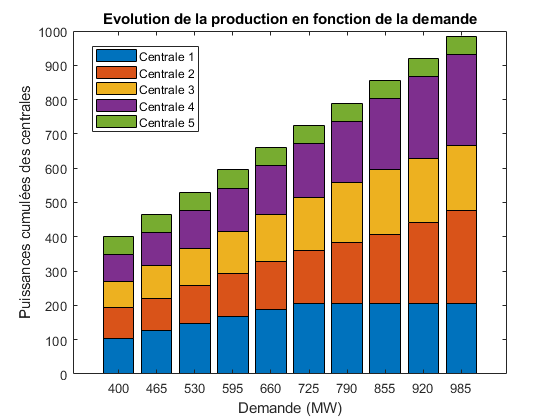

figure % Merci Mathieu
bar(Demandes,X,'stacked')
xlabel('Demande (MW)')
ylabel('Puissances cumulées des centrales')
title(sprintf(['Evolution de la production en fonction de la demande']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

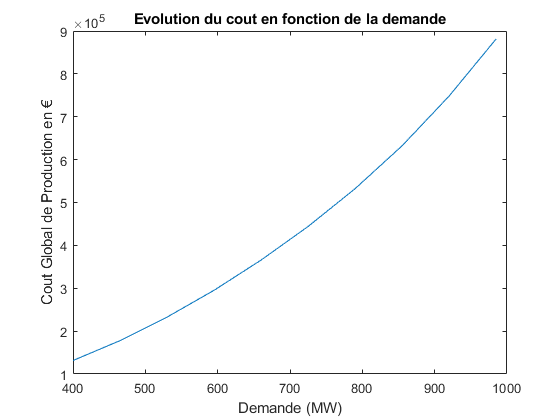

plot(Demandes,Cout_Global)
xlabel('Demande (MW)')
ylabel('Cout Global de Production en €')
title(sprintf(['Evolution du cout en fonction de la demande']))

## Partie 2

## 2.1) Fonction objectif

f2 = @(x) x.^2*D + x*E + 24*sum(F); % /24 pour avoir le résultat en kg/j

## 2.2) Définition des contraintes

Aineq2 = [];%les contraintes inégalités seront contenues dans les bornes
Bineq2 =[];
Aeq2 = [ones(1,length(Pmin))];
Beq2 =[400]; % valeur donnée dans l'énoncé

## 2.3) Définition des bornes

LB2 = [Pmin];%borne inférieure
UB2 =[Pmax];%borne supérieure
x02 = UB2'/2;% initialisation

## 2.4) Solver : fmincon + Affichage des résultats

[x2,fval2,flag2,output]=fmincon(f2,x02,Aineq2,Bineq2,Aeq2,Beq2,LB2,UB2,'',option);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.635399e+05    9.900e+01    4.986e+02
    1      12    1.255096e+05    9.205e+01    2.508e+02    5.622e+01
    2      18    1.143460e+05    7.891e+01    2.560e+02    2.208e+01
    3      24    1.140829e+05    7.858e+01    1.790e+02    4.461e-01
    4      30    1.071035e+05    6.086e+01    1.059e+02    1.518e+01
    5      36    8.878762e+04    2.272e+00    1.542e+02    3.518e+01
    6      42    8.778042e+04    0.000e+00    3.155e+01    1.821e+01
    7      48    8.770019e+04    0.000e+00    2.070e+00    5.497e+00
    8      54    8.770008e+04    0.000e+00    3.973e-01    4.006e-01
    9      60    8.770005e+04    0.000e+00    1.200e-03    1.313e-01
   10      66    8.770005e+04    5.684e-14    1.962e-05    2.144e-05

Local minimum found that satisfies the cons

if flag2 > 0 
        % si flag=1, toutes les conditions de détection de la solution sont vérifiées
        disp('Solution trouvée')
        disp('Valeurs de puissance')
        disp(x2)
        disp('Cout de production en €')
        disp(fval2)   
end

Solution trouvée


Valeurs de puissance


   71.6220   90.0000   68.0000  129.7628   40.6152



Cout de production en €


   8.7700e+04



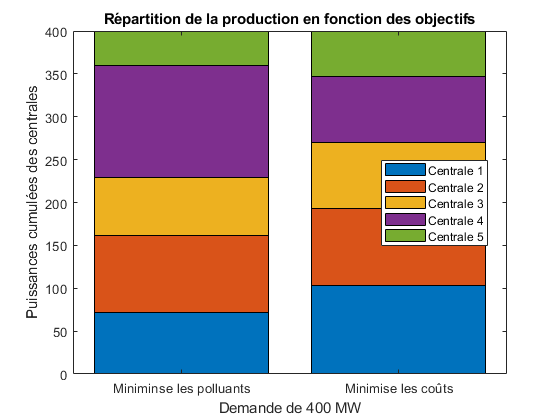

Xconca =[x2;X(1,:)];
Demande2 = categorical({'Miniminse les polluants','Minimise les coûts'});
figure 
bar(Demande2,Xconca,'stacked')
xlabel('Demande de 400 MW')
ylabel('Puissances cumulées des centrales')
title(sprintf(['Répartition de la production en fonction des objectifs']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

% On remarque que la Centrale 1 est très rentable mais pollue beaucoup.
% C'est tout l'inverse pour la centrale 4. 
% On peut aussi noter que dans les 2 cas, la centrale 2 est utilisée à la même puissance.

## Partie 3

## 3.1) Méthode de pondération

N=14;%nbr variable de points (N+1) à afficher sur la figure

f = @(x) x.^2*A+x*B+sum(C);  % pour pouvoir faire un "run section"
f2 = @(x) x.^2*D + x*E + 24*sum(F);

%Définition des contraintes, des bornes et initialisation

Aeq3=[ones(1,length(Pmin))];
Beq3=[400];
Aineq3=[];
Bineq3=[];
LB3=Pmin ;
UB3 = Pmax;
x03 = UB3'/2;

% Méthode de pondération avec w1 et w2 variants entre 0 et 1

f1val = [];
f2val = [];
for k =0:N
    f3 = @(x) k/N*f(x)+ (1-k/N)*f2(x)+0.3*f2(x);% taxe de 0.3 € par kg/j de polluants produits
    option=optimoptions('fmincon','display','iter');
    [x3,fval3,flag3,output]=fmincon(f3,x03,Aineq3,Bineq3,Aeq3,Beq3,LB3,UB3,'',option);
    f1val=[f1val;f(x3)];
    f2val=[f2val;f2(x3)];
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.126018e+05    9.900e+01    6.482e+02
    1      12    1.637982e+05    9.357e+01    3.244e+02    5.692e+01
    2      18    1.492243e+05    8.048e+01    3.003e+02    2.318e+01
    3      24    1.486371e+05    7.999e+01    2.134e+02    9.301e-01
    4      30    1.449221e+05    7.294e+01    1.130e+02    6.154e+00
    5      36    1.225188e+05    2.001e+01    2.352e+02    3.139e+01
    6      42    1.141316e+05    0.000e+00    3.893e+01    2.635e+01
    7      48    1.140144e+05    0.000e+00    5.524e+00    6.844e+00
    8      54    1.140110e+05    5.684e-14    2.543e+00    2.085e+00
    9      60    1.140101e+05    0.000e+00    1.274e-01    6.362e-01
   10      66    1.140101e+05    0.000e+00    5.759e-03    8.392e-03
   11      72    1.140101e+05    0.000e+00    1.788e-05    3.787e-04



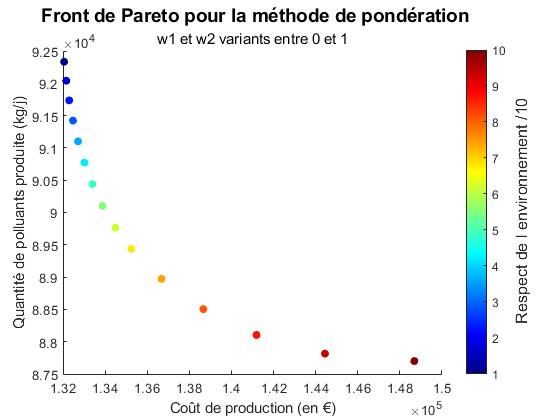


% Affichage des résultats

d = linspace(10,1,length(f1val));
scatter(f1val,f2val,[],d,'filled')
colormap jet
c = colorbar;
c.Label.String = '\fontsize{12} Respect de l environnement /10';
xlabel('Coût de production (en €)')
ylabel('Quantité de polluants produite (kg/j)')
title('\fontsize{14} Front de Pareto pour la méthode de pondération','w1 et w2 variants entre 0 et 1')

% 1) On ne prendra pas une solution produisant plus de 9*10^4 kg/j à cause
% de la pénalité financière importante qui est liée.
% 2) On pourra se servir du grapique en tant qu'outil d'aide à la décision afin de
% choisir entre les solutions optimales proposées par le Front de Pareto

## 3.2) Goal Attainment Method

% initialisation et contraintes

fun_totale = @(x)[x.^2*A+x*B+sum(C) ; x.^2*D + x*E + 24*sum(F)];% f1 et f2
weight = [1;1]; % valeurs prises par mimétisme des autres exemples vus dans la documentation
Aeq4=[ones(1,length(Pmin))];
Beq4=[400];
LB4=[Pmin];
UB4 =[Pmax];
x04 = UB4'/2;

% solver 

options = optimoptions('fgoalattain','Display','iter');
goal = [1.36*10^5;9*10^4];
[x,fval,factor,flag,output] = fgoalattain(fun_totale,x04,goal,weight,[],[],Aeq4,Beq4,LB4,UB4,'',options);


                 Attainment        Max     Line search     Directional 
 Iter F-count        factor    constraint   steplength      derivative   Procedure 
    0      7              0       96812.3                                            
    1     15     -1.916e+04     2.041e+04            1              -1     
    2     23           -910         726.8            1               1     
    3     31         -837.3         269.2            1           0.993     
    4     39         -614.2        0.1499            1               1     
    5     47         -614.1     2.712e-07            1               1     

Local minimum possible. Constraints satisfied.

fgoalattain stopped because the size of the current search direction is less than
twice the value of the 

while factor < 0 % signifie que l'objectif est atteint et n'est plus optimisable
    goal = [goal(1)-50;goal(2)]; % afin d'obtenir le coût de production minimal pour une pollution limite de 
    % 90 000 kg/j.
    [x,fval,factor,flag,output] = fgoalattain(fun_totale,x04,goal,weight,[],[],Aeq4,Beq4,LB4,UB4,'',options);
end


                 Attainment        Max     Line search     Directional 
 Iter F-count        factor    constraint   steplength      derivative   Procedure 
    0      7              0       96862.3                                            
    1     15     -1.915e+04     2.042e+04            1              -1     
    2     23         -890.8         712.4            1               1     
    3     31         -814.1           257            1           0.994     
    4     39         -600.8         0.137            1               1     
    5     47         -600.7     2.236e-07            1               1     

Local minimum possible. Constraints satisfied.

fgoalattain stopped because the size of the current search direction is less than
twice the value of the 

formatSpec = 'Pour une quantité limite de polluants émise de %4.2f kg/j, le coût de production le plus faible est de %8.3f €';
fprintf(formatSpec,goal(2),goal(1))

Pour une quantité limite de polluants émise de 90000.00 kg/j, le coût de production le plus faible est de 134000.000 €

% On pourrait réaliser un front de Pareto avec cette méthode.
% Néanmoins, il faudrait réaliser une boucle while dans une boucle for.
% Et pour avoir un nombre de boucles raisonnable, cela me semble compliqué.
% A moins d'avoir au préalable une idée précise de l'intervalle dans laquelle se trouve la solution.
% Ce qui n'est pas possible sans faire appel à d'autres fonctions en amont.
% Donc je ne vois pas vraiment l'utilité d'en réaliser un.

## Conclusions

A partir de l'ensemble des résultats obtenus, quelles sont vos conclusions générales sur l'optimum de fonctionnement ?  

Les valeurs optimales de coût de production se situent aux alentours de 131 000 €. Celles pour les quantités de polluants à 8780 kg/j. Malheureusement, ces valeurs ne peuvent cohabiter et on atteint un optimum multi-critère que l'on pourrait choisir comme ceci : coûts de production de 138 000€ et 8870kg/j de polluants émis.

## Annexe : aides pour les graphiques

Ci dessous des codes qui peut vous inspirer pour le tracé de graphiqes. Remerciements à Mathieu Milhé.

% % exemple 1 (valeurs numériques aléatoires choisies)
% Demande = 300:100:500;
% P=[70 95 120
%    70 85 105
%    70 85 100
%    50 80 100
%    40 55 75];
% 
% figure
% bar(Demande,P,'stacked')
% xlabel('Demande (MW)')
% ylabel('Puissances cumulées des centrales')
% title(sprintf(['Evolution de la bla bla bla ...en fonction de la demande']))
% legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

% % exemple 2 (valeurs numériques aléatoires choisies)
% x = categorical([{'Coût 1'}, {'Pollution 1'}]);
% P = [100 88 77 76 45];
% Q = [81 90 33 165 54];
% C1=1e5; Pol1=8e4; C2=1.5e5; Pol2=7e4;
% bar(x,[P;Q],0.3,'stacked')
% legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")
% title(sprintf('Coût minimal : %3.0f euros/MW pour %4.0f kg/h\nPollution minimale : %3.0f euros/MW pour %4.0f kg/h',...
%     C1,Pol1,C2,Pol2))

% % exemple 3 (valeurs numériques aléatoires choisies)
% X=1e5:0.2e5:2e5;
% Y=[12 11 9 8 7 5].*1e3;
% d = linspace(1,10,length(Y));
% scatter(Y,X,[],d)
% colormap winter
% c = colorbar;
% c.Label.String = 'Niveau de bl bla bla';
% xlabel('abscisse (unité)')
% ylabel('ordonnée (unité)')
% title('Front de Pareto pour bla bla bla avec bla bla variant entre bla bla et bla bla')